clc; clear all;
Gain = 0.1;
Bypass = false;
Type = true;
WetDryMix = 0.5;
fs = 48000;
Rvar = 1000;
asym_n = 1;
asym_p = 1;
Ra = 1000;
R6 = 51e3;
R4 = 4.7e3;
R5 = 10e3;
C4 = 51e-12;
C3 = .047e-6;
Voff = 4.5;
prec = 1e-6;
maxIter = 50;
%TEst DC Sweep
R = 1000;
Vt = 0.026;
eta = 1;
Is = 10^-12;

% TEst audio signal sin wave


[Vin, fs] = audioread("singing_female.wav");
Fs = fs;
Ts = 1/Fs;
%Vin2 = sin(2*pi*t*125);
%Vin3 = sin(2*pi*t*600);
%Vin = Vin + Vin2 + Vin3;


%Vin = x;
[N, channels] = size(Vin)

N = 272243

channels = 1

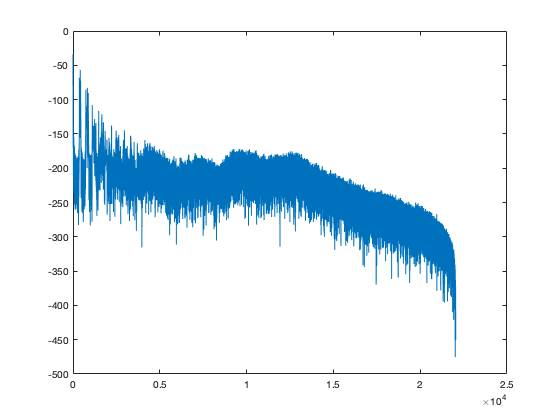

    Vout = zeros(size(Vin));
    channel = 1;
    asym_n = .01;
    asym_p = 2;
    Is_neg = Is / (asym_n * eta * Vt);
    Is_pos = Is / (asym_p * eta * Vt);
    b0 = 0.5;
    b1 = 0.5;
    a1 = 0.1;
    x = 0;
    xhold = zeros(1, 1);
    yhold = zeros(1, 1);
    g = 0.5;
    Vin = Vin+4.5;
    for n = 1:N
        i = 1;          %positive diode                                                             %negative diode
        fx = x/R + Is * (exp(x/(asym_p * eta*Vt))-1) - Vin(n,channel)/R + -Vout(n,channel)/R - Is * (exp(-x/(asym_n*eta*Vt))-1);
        %Solve for voltage at each sample
        while(i < maxIter && (abs(fx)> prec))
            %Take dirivitive to and solve using newton raphson method
            den = 1/R + Is_pos * (exp(x/(asym_p * eta*Vt)))+ Is_neg * (exp(-x/(asym_n*eta*Vt)));
            x = x - (fx/den);
            i = i + 1;
            fx = x/R + Is * (exp(x/(asym_p * eta*Vt))-1) - Vin(n,channel)/R + -Vout(n,channel)/R - Is * (exp(-x/(asym_n*eta*Vt))-1);
        end
        Vout(n,channel) =  b0 * x + b1 * xhold - a1 * yhold;
        %update state variables
        yhold = Vout(n, channel);
        xhold = x;
    end
    xdft = fft(Vout);
    xdft = xdft(1:floor(N/2+1));
    psdx = (1/(Fs*N)) * abs(xdft).^2;
    psdx(2:end-1) = 2*psdx(2:end-1);
    psdx = 10 * log(psdx);
    freq = 0:Fs/length(Vin):Fs/2;
    figure;
 Vin   
%find local maximums, store in localMax
bins = [20,39, 40,79, 80,159, 160,319, 320,639, 640 1279 1280 2559 2560 5119  5120 10239 10240 20000];
localMax = zeros(10, 2);
k = 1;    
for i = 1:2:20
    currentBin = bins(i:i+1);
    currMaxAmp = -inf;
    currMaxFreq = 1;
    for j = currentBin(1):currentBin(2)
        psdx(j);
        if psdx(j) > currMaxAmp
            currMaxAmp = psdx(j);
            currMaxFreq = j;
        end
    end
    localMax(k, 1) = currMaxFreq;
    localMax(k, 2) = currMaxAmp;
    k = k + 1;
end

%once we have local maximums, then we go through and find maximum there
currMaxAmp = -inf;
found = false;
harms = zeros(7, 1);
for i = 1:10
    
    if localMax(i, 2) > currMaxAmp
        currMaxAmp = localMax(i, 2);
        currMaxFreq = localMax(i, 1);
    end
end
for i = 1:10
    if found
        harms(j) = localMax(i, 1);
        j = j + 1;
    end
    if currMaxFreq == localMax(i, 1)
        harms(1) = currMaxFreq;
        found = true;
        j = 2;
    end
end
currMaxAmp;
currMaxFreq;
harms;
xdft = fft(Vout);
xdft = xdft(1:floor(N/2+1));
psdx = (1/(Fs*N)) * abs(xdft).^2;
psdx(2:end-1) = 2*psdx(2:end-1);
psdx = 10 * log(psdx);
freq = 0:Fs/length(Vin):Fs/2;
figure;
plot(freq, psdx)

harms 

harms =         2568
        5129
       10258
           0
           0
           0
           0


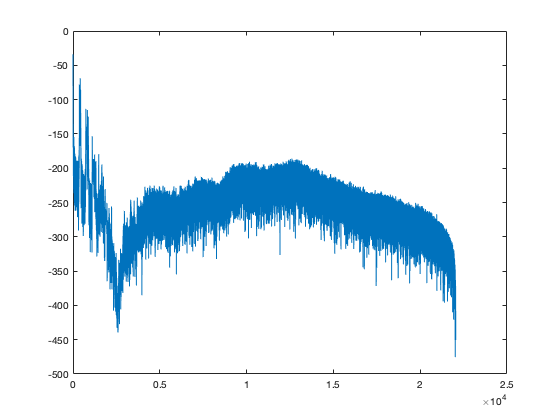

[b, a] = iirnotch((harms(2)-1)/fs, .5, 3); 
signal = filter(b, a, Vout);
signal = filter(b, a, signal);
%phased = ((sin(2*pi*(harms(2)-1)*t)));
%signal = Vout + phased;
xdft = fft(signal);
xdft = xdft(1:floor(N/2+1));
psdx = (1/(Fs*N)) * abs(xdft).^2;
psdx(2:end-1) = 2*psdx(2:end-1);
psdx = 10 * log(psdx);
freq = 0:Fs/length(Vin):Fs/2;
sound(signal, fs)
figure;

plot(freq, psdx)



localMax;


    %Graph two wavelengths
%Plot two periods of input and output waveform
lim = ((1/f)*48000)*2;

Unrecognized function or variable 'f'.

figure
plot(t(1:lim), Vin(1:lim), t(1:lim), Vout(1:lim));

    db = 20*log(fftsig);
    f = 0:length(db)-1;
    %L = length(db)
    %l = length(f)
    figure;
    plot(f, db);
    xlabel("Frequency (Hz)");
    ylabel("Amplitude dB");
    xticklabels({20, 50, 100, 200, 500, 1000, 2000, 5000, 10000, 20000});
    set(gca, 'XScale', 'log');
    set(gca, 'XTick', [ 20, 50, 100, 200, 500, 1000, 2000, 5000, 10000, 20000]);
    xlim([20 24000]);
    